Assignment 4

Apratim Mukherjee CSE D

The goal of this project was to create a makeshift Face ID which are used in most of the smartphones that came out recently. The approach taken by me is quite primitive and wouldn't hold in the real world. Instead of using triplet loss, I used a simple classifier which is trained on my images and a couple of random images of people for the negative class. I used the Histogram of Oriented Gradients Feature Extractor to train my linear SVM. The results are sub optimal because of lack of data. The classifier is later used in an app which takes an image from from the video stream of the webcam.

% Load my images and negative examples from the paths
myFace = imageSet('verific\resized','recursive');
otherFaces = imageSet('images\dataset','recursive');
num = otherFaces.Count + myFace.Count;
trainingFeatures = zeros(num,4680);
count = 1;

% Extracting the features from all images of my face
for i = 1:myFace.Count
    img = readimage(myFace, i);
    img = rgb2gray(img);   % Might have to comment if image
    img = imbinarize(img); % is already in grayscale
    trainingFeatures(i,:) = extractHOGFeatures(img);
    count = count + 1;
end

% Extracting the features from images of other faces
for i = 1:otherFaces.Count
    img = readimage(otherFaces, i);
    img = rgb2gray(img);   % Might have to comment if image
    img = imbinarize(img); % is already in grayscale
    trainingFeatures(count,:) = extractHOGFeatures(img);
    count = count + 1;
end

% Preparing the labels for the images in the dataset.
% if trainingLabels(i) = 1  -> My face
% if trainingLabels(i) = 0  -> Not my face
trainingLabels = zeros(num,1);
for i = 1:num
    if i <= myFace.Count
        trainingLabels(i) = 1;
    end
end

% Fitting the classifier according to the features and
% labels provided in the dataset.
classifier = fitcecoc(trainingFeatures, trainingLabels);
% Saving the classifier so it can be loaded anytime once
% it has been trained.
save('classifier.mat','classifier');

All of the above code is for training a classifier using the data provided by the user. Below are the few important functions used in the app.

The image from the webcam is continuously received and displayed in the app till the user decides on a final image. Once 'Fix Image' is clicked, the last image from the stream is selected for processing. After this, 'Verify' is clicked and the classifier decides if the face is a match or not. First, a Haar Cascade Face detector is run on the image. If a face is not detected, the lamp stays red and 'No Face Detected' is displayed. If a face is detected, the image is cropped to only keep the face and then resized to fit the specifications of the classifier ([92, 112]). This image is displayed on the UIAxes. After this, the image is grayscaled and binarized and HOG features are extracted, which is then run through the classifier for a prediction. If the classifier predicts a 1, it means that the face detected was my face and the lamp should turn green with a message saying 'Unlock'. If the face is not a match, the lamp stays red with a message saying 'No Match'.

- Switch the VideFeed on.

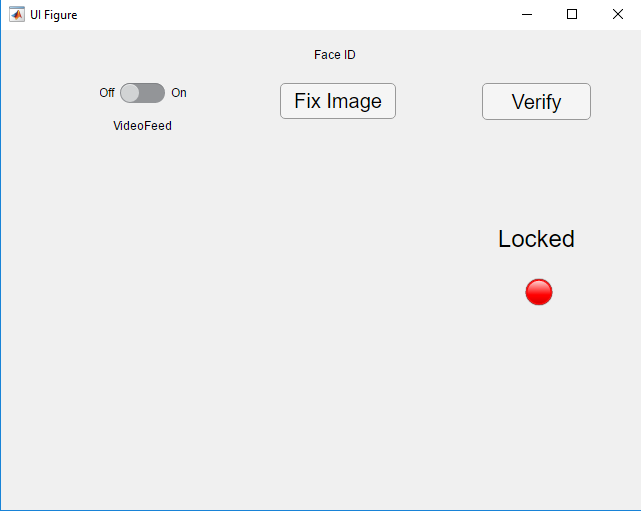

            2.  Click on Fix Image when you're ready for verification.

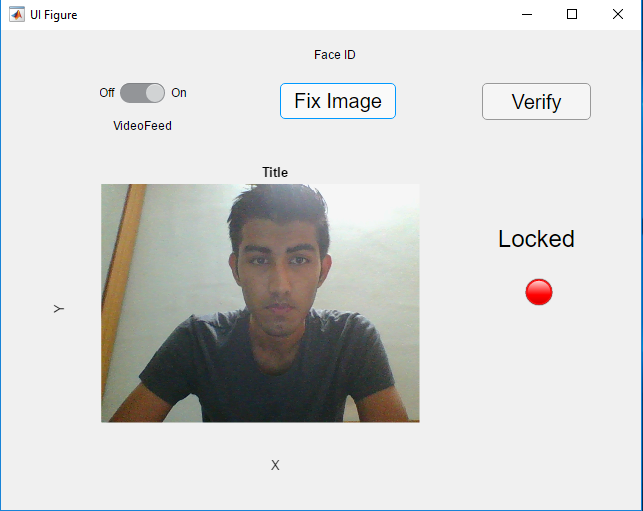

            3.  Click on Verify to check if the face matches or not.

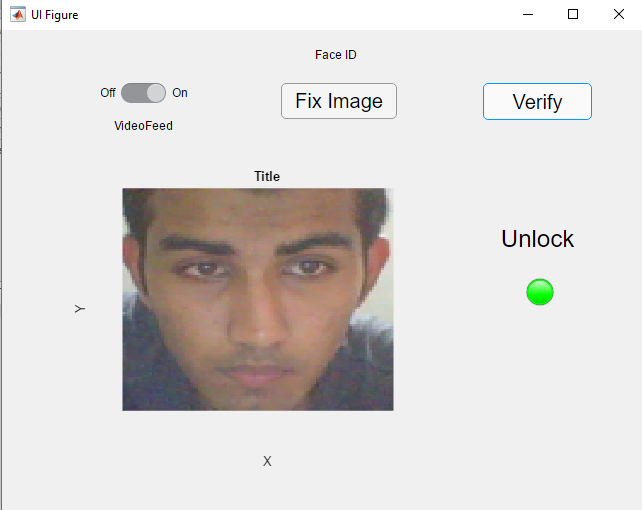

            4.  If you Verify when there's no face, 'No Face Detected' is displayed.

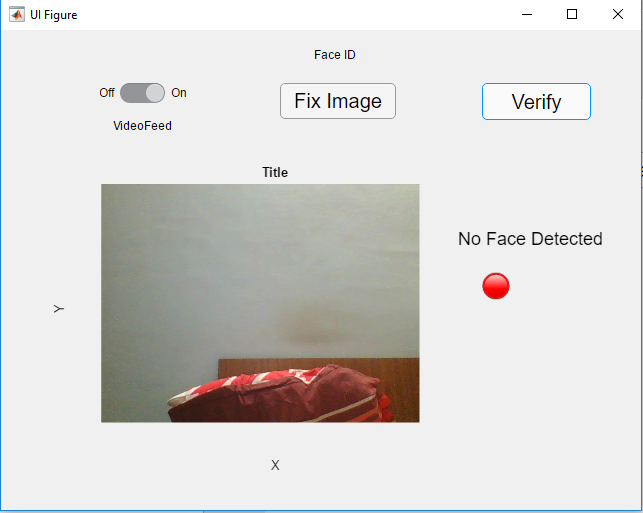

             5. If another person verifies instead of me, it stays locked and displays 'No Match'.    

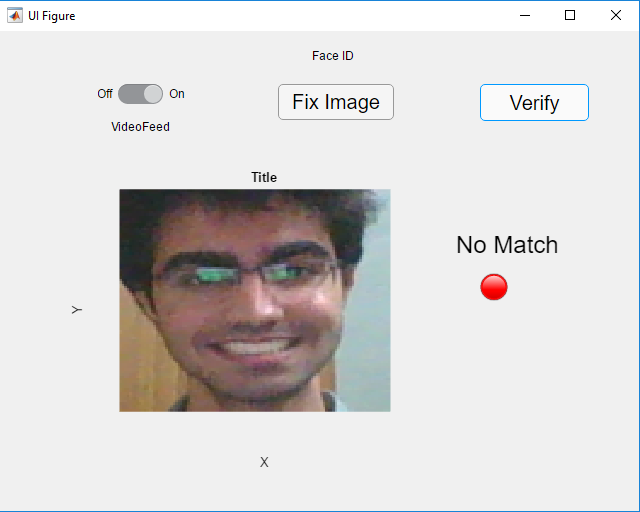

function VideoFeedSwitchValueChanged(app, event)
    value = app.VideoFeedSwitch.Value;
    if value == 'On'
        cam = webcam(1);
        app.UIAxes.Visible = 'on';
        while true
            app.img = snapshot(cam);
            imshow(app.img,'parent',app.UIAxes);
            if app.breakflag == 1
                clear cam
                break
            end
        end
    end
end

function FixImageButtonPushed(app, event)
    app.breakflag = 1;
end


function VerifyButtonPushed(app, event)
    detect = vision.CascadeObjectDetector();
    bbox = step(detect,app.img);
    if isempty(bbox)
        app.LockedLabel.Text = 'No Face Detected';
    else
        dispimg = imcrop(app.img,bbox);
        dispimg = imresize(dispimg, [92,112]);
        imshow(dispimg,'parent',app.UIAxes);
        dispimg = rgb2gray(dispimg);
        dispimg = imbinarize(dispimg);
        load('classifier.mat');
%         classifier = fitcecoc(trainingFeatures, trainingLabels);
        dispimgF = extractHOGFeatures(dispimg);
        pred = predict(classifier,dispimgF);
        if pred == 1
            app.LockedLabel.Text = 'Unlock';
            app.Lamp.Color = [0 1 0];
        else
            app.LockedLabel.Text = 'No Match';
        end
    end
end